# The "price" of mobile coverage

## Introduction

The range of a cell depends on the Base stations’ transmit power. 

Higher transmit power (obviously) gives larger cells and therefore the same area can be covered with fewer cells.

In this exercise, we will use network modelling and simulation to understand the relationship between:

- Base station maximum transmission power.

- Base station transmission propagation and coverage area

- Power consumption

This will allow us to understand the *price* of the coverage of a mobile network, in terms of power consumption.

## Simulations

For this exercise, we will be using an LTE simulator called MONSTeR built in Matlab. 

The tool can be used in 3 different ways:

- **Using Matlab**: this is the option that allows the most control and flexibility.

- **Matlab app**: a GUI for the simulator is available in ***monster/app/monster.mlapp:*** the app exposes some of the most common settings, allows to run the simulation and save a result file that can be then used in Matlab to create plots

- **Standalone MONSTeR app: **the GUI/app in point 2 is also available as a standalone software that can be installed in a Windows PC. This option does not require Matlab installed, but a *Matlab runtime* will be downloaded and installed (unless already present).

In the following, we will focus on option 2 for running the simulation and then continue the processing of the results generated in Matlab.

### Setting up the scenario

Open the MONSTeR app and navigate to the **Setup **tab and set the following values (if a certain parameter is not specified, simply leave the default value)

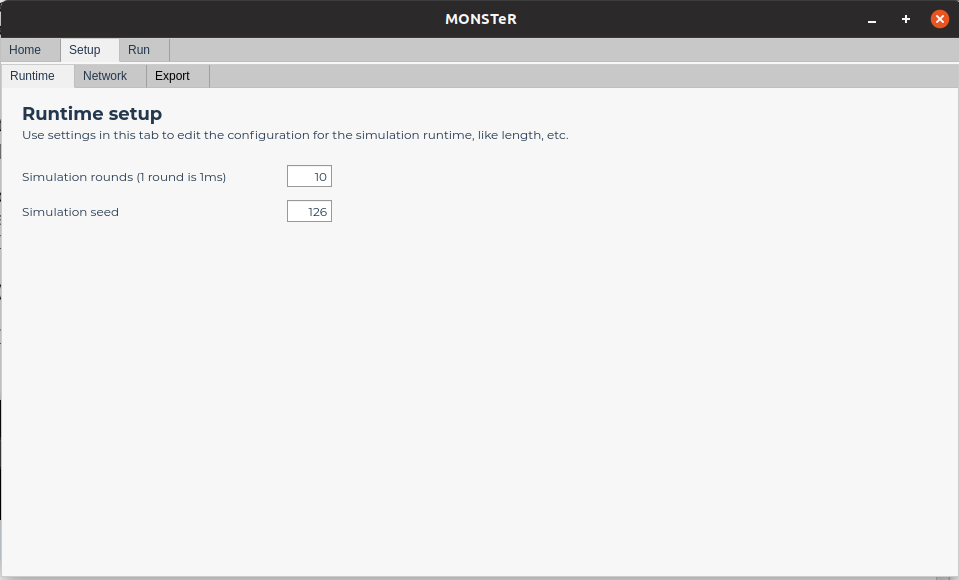

#### Runtime

- Simulation rounds: 5

#### Network

- Macro cells per site: 1

- Macro eNodeB max TX power: 5 (we will also use the values 20 and 80 later on)

- Micro eNodeB sites: 0

- Downlink frequency: leave default value, we will also use the value 800 later on

- Number of UEs: 5

### Running the simulation

Once the setup is completed, head to the **Run** tab and click the **Load setup** button to generate a configuration based on the settings chosen.

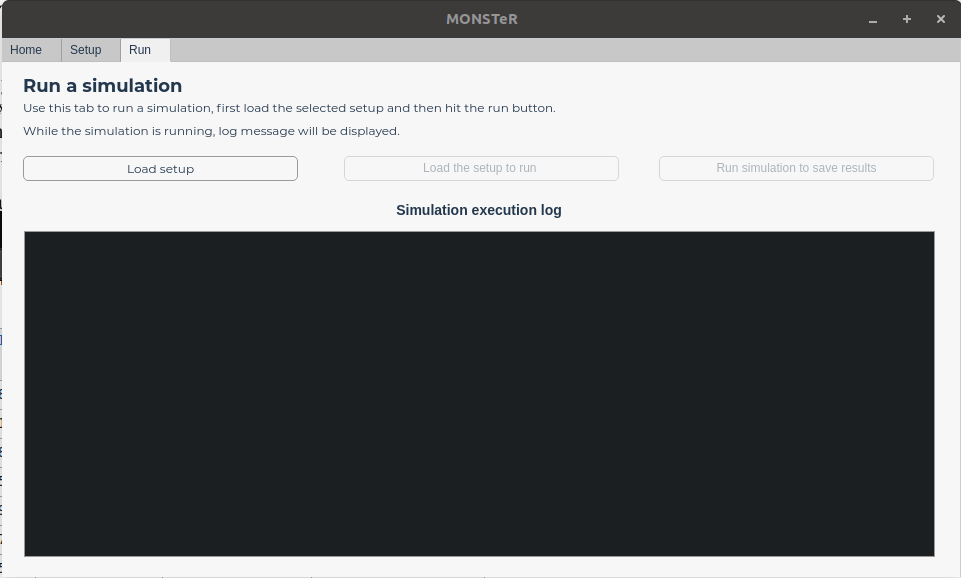

Once the setup is loaded, it will be possible to run the simulation. Click on the **Run** button and wait until the **Simulation execution log **will print out that the simulation is completed.

At this point it will be possible to save the results of this simulation by clicking the **Save results** button.

*In the following, we will suggest some names and folders for saving the results files. These are by no means mandatory, feel free to change them to whatever suits you best, but remember to edit the code that will follow below in case you choose differently.*

When prompted to save the results, save the file as:

- ***monster/examples/live/mobileCoveragePower/results_{max_pow}.mat***

Where you should replace the *** {max_pow} ***with the value used for the *Macro eNodeB max TX power*, so in this case the results file will be ***results_5.mat***.

Now repeat the same steps and run the same simulation by just changing the value for the *Macro eNodeB max TX power* to 20 and 80.

## Results analysis

### Loading the results

Once the 3 simulations are completed, run the following piece of code that will load the results files in this live script (if you did not use the default naming described above, remember to modify paths and filenames accordingly).

We should also make sure to have a copy of the UEs and the eNodeB used in the simulations for calculating their relative distance. We just need to do this once, since all the simulations are based on the same seed, so parameters like the position and the trajectory along which the users move are the same regardless of other parameter changes.

resultsPath = 'examples/live/mobileCoveragePower/';
fileNames = {'results_5.mat', 'results_20.mat', 'results_80.mat'};
simulationRounds = 5;
numberUsers = 5;
combinedResults = struct(...
    'power', zeros(length(fileNames), simulationRounds), ...
    'sinr', zeros(length(fileNames),numberUsers, simulationRounds), ...
    'meanSinr', zeros(length(fileNames), numberUsers),...
    'rxPower', zeros(length(fileNames),numberUsers, simulationRounds), ...
    'meanRxPower', zeros(length(fileNames), numberUsers));
for iFile = 1:length(fileNames)
    fileName = strcat(resultsPath, fileNames{iFile});
    load(fileName)
    combinedResults.power(iFile, :) = Simulation.Results.powerConsumed;
    combinedResults.sinr(iFile, :, :) = Simulation.Results.wideBandSinrdB;
    combinedResults.meanSinr(iFile, :) = mean(Simulation.Results.wideBandSinrdB, 1);
    combinedResults.rxPower(iFile, :, :) = Simulation.Results.receivedPowerdBm;
    combinedResults.meanRxPower(iFile, :) = mean(Simulation.Results.receivedPowerdBm, 1);
    if iFile == length(fileNames)
        % In the last iteration, save also the users and the eNodeB
        users = Simulation.Users;
        eNodeB = Simulation.Cells;
    end
    clear Simulation;
end


### Plotting the results

The variable ***combinedResults ***now holds all the results from the 3 different simulations.

We can begin looking at the results with some simple plots of the average power consumed by the network in the 3 cases:

seriesColoursHex = {'#C1232B', '#27727B', '#FCCE10'};
seriesColoursRgb = [0.7569 0.1373 0.1686; 0.1529 0.4471 0.4824; 0.9882 0.8078 0.0627];

meanPower = mean(combinedResults.power, 2);
figure
xBar = categorical({'5 W', '20 W', '80 W'});
xBar = reordercats(xBar, {'5 W', '20 W', '80 W'});
barChart = bar(xBar, meanPower);
barChart.FaceColor = 'flat';
barChart.CData = seriesColoursRgb;
drawnow
xlabel('eNodeB max TX power [W]')
ylabel('Average network power consumed [W]')
title('Network power consumption')


We can now examine some user-side metrics. This will allow us to find out the relationship between the maximum transmission power of the eNodeB, the received power at the UE and the distance between the UE and the eNodeB.

When calculating the distance between the users and the eNodeB, we can assume the users to be static, given that by default they move with pedestrian speed, but we simulated for a very short amount of time (5ms), so the variation is negligible. 

distances = zeros(length(users), 1);
eNodeBPos = [eNodeB.Position(1), eNodeB.Position(2)];
for iUser = 1:length(users)
    userPosition = [users(iUser).Position(1), users(iUser).Position(2)];
    distances(iUser) = norm(userPosition - eNodeBPos);
end


Now that we have the distances for the users, we can generate the plots based on the mean recevied SINR and the mean received power that we calculated above.

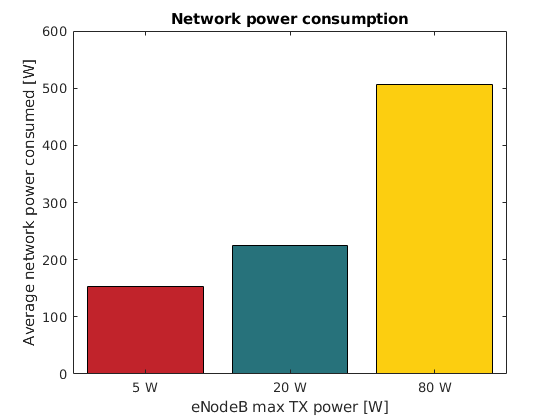

figure;
for iSeries = 1:size(combinedResults.power, 1)
    scatter(distances, combinedResults.meanSinr(iSeries, :),...
        'MarkerEdgeColor', seriesColoursHex{iSeries},...
        'MarkerFaceColor',seriesColoursHex{iSeries},...
        'LineWidth',1.5);
    hold on;
    drawnow;
end

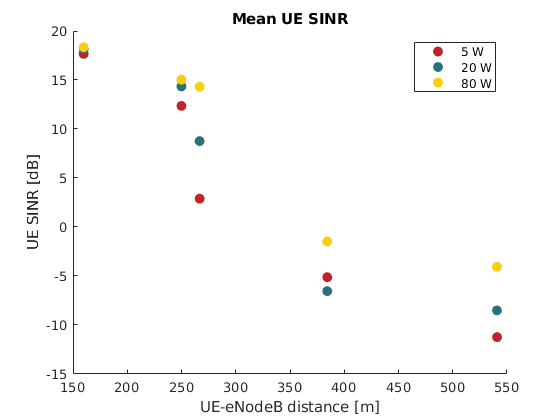

xlabel('UE-eNodeB distance [m]')
ylabel('UE SINR [dB]')
title('Mean UE SINR')
legend('5 W', '20 W', '80 W');

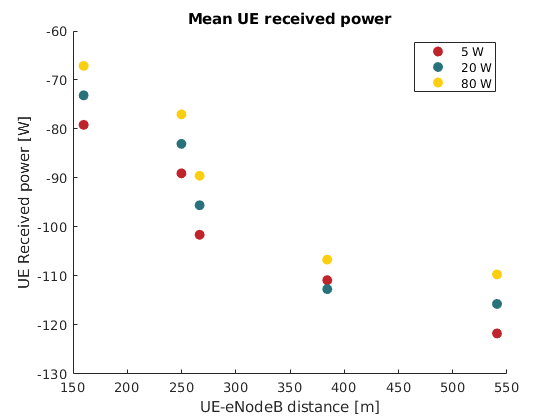


figure;
for iSeries = 1:size(combinedResults.power, 1)
    scatter(distances, combinedResults.meanRxPower(iSeries, :), ...
        'MarkerEdgeColor', seriesColoursHex{iSeries},...
        'MarkerFaceColor',seriesColoursHex{iSeries},...
        'LineWidth',1.5);
    hold on;
    drawnow;
end
xlabel('UE-eNodeB distance [m]')
ylabel('UE Received power [dBm]')
title('Mean UE received power')
legend('5 W', '20 W', '80 W');